# Trading Investment Strategy

## Clear workspace

clear; clc;

## Load Data

% readtimetable ("Trend Trading Input Output Data.xlsx", "Sheet","Price Data")

tic

priceTT = readtimetable ("Trend Trading Input Output Data.xlsx", ...
    "Sheet", "Price Data");

volumeTT = readtimetable ("Trend Trading Input Output Data.xlsx", ...
    "Sheet", "Volume Data");

benchmarkTT = readtimetable ("Trend Trading Input Output Data.xlsx", ...
    "Sheet", "IHSG Data");


toc

Elapsed time is 39.926201 seconds.


## Data cleaning

tic

any (isempty(priceTT))

ans = logical
   0



priceTT = fillmissing (priceTT, 'previous');
priceTT = fillmissing (priceTT, 'next');
head (priceTT);

priceTTempty = any (isempty(priceTT))

priceTTempty = logical
   0


volumeTTempty = any (isempty(priceTT))

volumeTTempty = logical
   0


benchmarkTTempty = any (isempty(priceTT))

benchmarkTTempty = logical
   0



toc

Elapsed time is 0.532827 seconds.


## Inspection 

Cumulative return

tic

cumret = ret2tick (tick2ret (priceTT));
cumretvar = cumret.Variables; 
cumretend = cumretvar (end,:);


% pick sym with cumret > 10 only 

cumretThreshold = 10;
buyidx = cumretend > cumretThreshold;
cumretendHighValue = cumretend(buyidx);
cumretendHighSymb = cumret.Properties.VariableNames (buyidx);

varname = "cumretEndValue";
A = array2table (transpose(cumretendHighValue), ...
    'VariableNames', varname);
B = array2table (transpose(cumretendHighSymb), ...
    "VariableNames", "BuyAndHoldSymbols");

cumretT = [B A];
cumretT = sortrows (cumretT,varname,"descend")

cumretT = 43×2 table
    BuyAndHoldSymbols    cumretEndValue
    _________________    ______________

        {'GMTD'}             113.78    
        {'ARTO'}              58.96    
        {'KONI'}             54.054    
        {'SLIS'}             47.436    
        {'TOWR'}             38.217    
        {'PSAB'}              37.27    
        {'TCPI'}             34.188    
        {'ABDA'}             32.539    
        {'EMTK'}             30.959    
        {'STTP'}                 28    
        {'INAF'}             26.988    
        {'TGKA'}             26.324    
        {'DEFI'}             25.715    
        {'DCII'}             22.476    
        {'MTDL'}             22.122    
        {'DNET'}             20.723    



SymSample = cumretT.BuyAndHoldSymbols; 
SymSample  = string (SymSample (2))

SymSample = "ARTO"

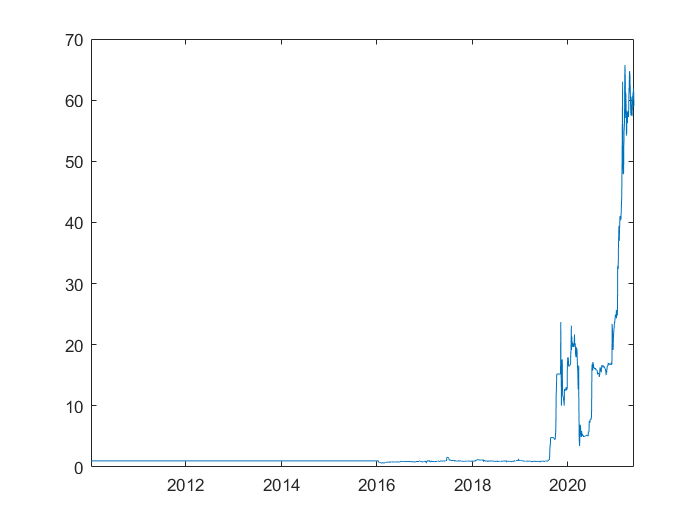


plot (cumret.Time, cumret.(SymSample))


toc

Elapsed time is 0.491576 seconds.


Selected subdataset

tic

SelectedVarNames = cumretendHighSymb;
SelectedVarNames = sort (SelectedVarNames);
priceSampleTT = priceTT (:, SelectedVarNames);
volumeSampleTT = volumeTT (:,SelectedVarNames);

head (priceSampleTT)

ans = 8×43 timetable
       Time         ABDA     AMRT    ARNA     ARTO     BRNA      CENT     CLEO    CPIN    CSMI    DCII     DEFI      DNET     EKAD     EMTK     ERTX     GEMA    GMTD    INAF     INDS      ITMA     JECC    JTPE    KAEF    KONI    MAPI    MARK     MREI      MTDL      MYOR      PSAB     PTDU    PTSP    SCMA    SKLT    SLIS    STTP    TCPI

head (volumeSampleTT)

ans = 8×43 timetable
       Time        ABDA     AMRT       ARNA       ARTO       BRNA          CENT       CLEO       CPIN       CSMI    DCII    DEFI       DNET          EKAD          EMTK       ERTX    GEMA    GMTD       INAF       INDS     ITMA    JECC     JTPE       KAEF       KONI       MAPI      MARK       MREI          MTDL          MYOR       PSAB    PTDU    PTSP      SCMA       SKLT    


toc

Elapsed time is 0.339458 seconds.


Save  database


save TrendTrading.mat priceTT volumeTT
% clear priceTT volumeTT

## Build signal

### Main absolute momentum

tic 

% Main absolute momentum

mainMomWindowSize = 40;
mainMomRetresh = 15/100;

% Shift row as windowSize steps
A = priceSampleTT.Variables;
TempPriceSampleTShift = priceSampleTT;
B = TempPriceSampleTShift.Variables ;
B (mainMomWindowSize+1:end,:) = A (mainMomWindowSize: end-1,:); 
TempPriceSampleTShift.Variables = B;

clear A B 

tail (priceSampleTT)

ans = 8×43 timetable
       Time        ABDA    AMRT    ARNA    ARTO     BRNA    CENT    CLEO    CPIN    CSMI    DCII     DEFI    DNET    EKAD    EMTK    ERTX    GEMA    GMTD     INAF    INDS    ITMA    JECC    JTPE    KAEF    KONI    MAPI    MARK    MREI    MTDL    MYOR    PSAB    PTDU    PTSP    SCMA    SKLT    SLIS    STTP    TCPI    TECH

tail (TempPriceSampleTShift)

ans = 8×43 timetable
       Time        ABDA    AMRT    ARNA    ARTO     BRNA    CENT    CLEO    CPIN    CSMI    DCII     DEFI    DNET    EKAD    EMTK    ERTX    GEMA    GMTD     INAF    INDS    ITMA    JECC    JTPE    KAEF    KONI    MAPI    MARK    MREI    MTDL    MYOR    PSAB    PTDU    PTSP    SCMA    SKLT    SLIS    STTP    TCPI    TECH


A = (priceSampleTT.Variables ./ TempPriceSampleTShift.Variables) -1 ;
A (1:mainMomWindowSize,:) = 0; 

max (max (A))

ans = 0.3587

min (max (A))

ans = 0.1975


% Signal

mainMomSignal = priceSampleTT; 
mainMomSignal.Variables = (A > mainMomRetresh);
tail (mainMomSignal)

ans = 8×43 timetable
       Time        ABDA    AMRT    ARNA    ARTO    BRNA    CENT    CLEO    CPIN    CSMI    DCII    DEFI    DNET    EKAD    EMTK    ERTX    GEMA    GMTD    INAF    INDS    ITMA    JECC    JTPE    KAEF    KONI    MAPI    MARK    MREI    MTDL    MYOR    PSAB    PTDU    PTSP    SCMA    SKLT    SLIS    STTP    TCPI    TECH


clear A

A = max (mainMomSignal.Variables, [], 1)

A =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


sum (A)

ans = 43


clear A TempPriceSampleTShift 


% mainMomBufferSignal 

mainMomBuffWindSize = 12; % Tag input parameter
mainMomBufferSignal = mainMomSignal;
A = mainMomSignal.Variables;
B = movmax (A, mainMomBuffWindSize, 1);
mainMomBufferSignal.Variables = B;

head (mainMomBufferSignal)

ans = 8×43 timetable
       Time        ABDA    AMRT    ARNA    ARTO    BRNA    CENT    CLEO    CPIN    CSMI    DCII    DEFI    DNET    EKAD    EMTK    ERTX    GEMA    GMTD    INAF    INDS    ITMA    JECC    JTPE    KAEF    KONI    MAPI    MARK    MREI    MTDL    MYOR    PSAB    PTDU    PTSP    SCMA    SKLT    SLIS    STTP    TCPI    TECH

tail (mainMomBufferSignal)

ans = 8×43 timetable
       Time        ABDA    AMRT    ARNA    ARTO    BRNA    CENT    CLEO    CPIN    CSMI    DCII    DEFI    DNET    EKAD    EMTK    ERTX    GEMA    GMTD    INAF    INDS    ITMA    JECC    JTPE    KAEF    KONI    MAPI    MARK    MREI    MTDL    MYOR    PSAB    PTDU    PTSP    SCMA    SKLT    SLIS    STTP    TCPI    TECH


clear A B
A = SymSample;  
B = mainMomBufferSignal (:, A)

B = 2825×1 timetable
       Time        ARTO
    ___________    ____

    04-Jan-2010     0  
    05-Jan-2010     0  
    06-Jan-2010     0  
    07-Jan-2010     0  
    08-Jan-2010     0  
    11-Jan-2010     0  
    12-Jan-2010     0  
    13-Jan-2010     0  
    14-Jan-2010     0  
    15-Jan-2010     0  
    18-Jan-2010     0  
    19-Jan-2010     0  
    20-Jan-2010     0  
    21-Jan-2010     0  
    22-Jan-2010     0  
    25-Jan-2010     0  


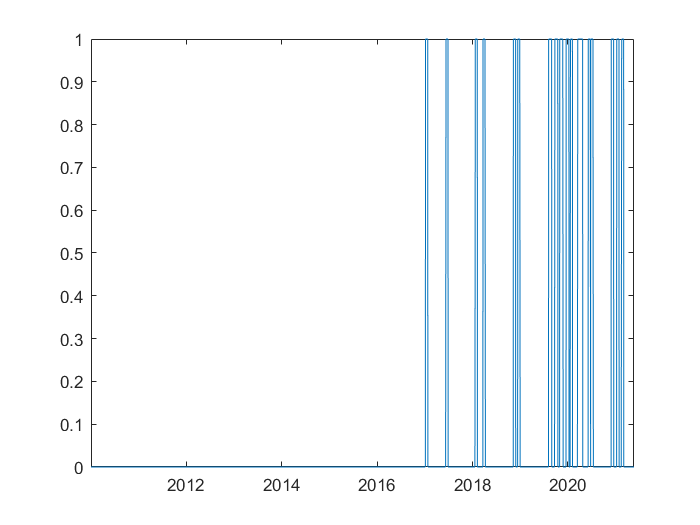

plot (B.Time, B.Variables )


clear A B mainMomSignal

toc

Elapsed time is 1.048576 seconds.


### Minimum Value Screener

tic

valueThresh = 20*10^9;
valueSampleTT = priceSampleTT;

valueSampleTT.Variables = ...
    priceSampleTT.Variables .* volumeSampleTT.Variables;
valueSampleTT = fillmissing (valueSampleTT, "constant", 0);
any (isempty(valueSampleTT))

ans = logical
   0


head (valueSampleTT)

ans = 8×43 timetable
       Time           ABDA         AMRT         ARNA       ARTO      BRNA         CENT      CLEO       CPIN       CSMI    DCII    DEFI      DNET         EKAD          EMTK       ERTX     GEMA    GMTD        INAF          INDS       ITMA       JECC         JTPE         KAEF         KONI         MAPI       MARK       MREI          MTDL          MYOR       PSAB    PTDU    PTSP        SCMA       

tail (valueSampleTT)

ans = 8×43 timetable
       Time          ABDA          AMRT          ARNA          ARTO         BRNA          CENT          CLEO          CPIN         CSMI          DCII          DEFI          DNET          EKAD          EMTK          ERTX          GEMA       GMTD       INAF          INDS          ITMA         JECC          JTPE          KAEF          KONI          MAPI          MARK         MREI          MTDL          MYOR          PSAB          PTDU



minValueSignal = valueSampleTT;
minValueSignal.Variables = valueSampleTT.Variables > valueThresh;
head (minValueSignal)

ans = 8×43 timetable
       Time        ABDA    AMRT    ARNA    ARTO    BRNA    CENT    CLEO    CPIN    CSMI    DCII    DEFI    DNET    EKAD    EMTK    ERTX    GEMA    GMTD    INAF    INDS    ITMA    JECC    JTPE    KAEF    KONI    MAPI    MARK    MREI    MTDL    MYOR    PSAB    PTDU    PTSP    SCMA    SKLT    SLIS    STTP    TCPI    TECH

tail (minValueSignal)

ans = 8×43 timetable
       Time        ABDA    AMRT    ARNA    ARTO    BRNA    CENT    CLEO    CPIN    CSMI    DCII    DEFI    DNET    EKAD    EMTK    ERTX    GEMA    GMTD    INAF    INDS    ITMA    JECC    JTPE    KAEF    KONI    MAPI    MARK    MREI    MTDL    MYOR    PSAB    PTDU    PTSP    SCMA    SKLT    SLIS    STTP    TCPI    TECH


A = max (minValueSignal.Variables)

A =      0     1     1     1     1     1     1     1     0     0     0     1     1     1     0     1     0     1     1     0     1     1     1     0     1     1     0     1     1     1     0     0     1     0     1     0     1     0     0     1     1     1     1


sum (A)

ans = 28


B = minValueSignal.Properties.VariableNames;
sort (transpose (B (logical(A))))

ans = 28×1 cell array
    {'AMRT'}
    {'ARNA'}
    {'ARTO'}
    {'BRNA'}
    {'CENT'}
    {'CLEO'}
    {'CPIN'}
    {'DNET'}
    {'EKAD'}
    {'EMTK'}
    {'GEMA'}
    {'INAF'}
    {'INDS'}
    {'JECC'}
    {'JTPE'}
    {'KAEF'}
    {'MAPI'}
    {'MARK'}
    {'MTDL'}
    {'MYOR'}
    {'PSAB'}
    {'SCMA'}
    {'SLIS'}
    {'TCPI'}
    {'TOWR'}
    {'TPIA'}
    {'ULTJ'}
    {'ZBRA'}



clear A B valueSampleTT

toc

Elapsed time is 0.774818 seconds.


### Volume Surge Screener

### Non-Continuous Liquidity Screener

### **Momentum Continuity Screener**

### Final Signal

tic

% finalSignal to be updated when new signal feature is added

finalSignal = priceSampleTT;
finalSignal.Variables = mainMomBufferSignal.Variables .* minValueSignal.Variables;

% Shift 1 day forward to avoid look ahead bias

A = finalSignal.Variables;
B = A;
B (2:end,:) = A (1:end-1,:);
B (1,:) = 0;
finalSignal.Variables = B;

head (finalSignal)

ans = 8×43 timetable
       Time        ABDA    AMRT    ARNA    ARTO    BRNA    CENT    CLEO    CPIN    CSMI    DCII    DEFI    DNET    EKAD    EMTK    ERTX    GEMA    GMTD    INAF    INDS    ITMA    JECC    JTPE    KAEF    KONI    MAPI    MARK    MREI    MTDL    MYOR    PSAB    PTDU    PTSP    SCMA    SKLT    SLIS    STTP    TCPI    TECH

tail (finalSignal)

ans = 8×43 timetable
       Time        ABDA    AMRT    ARNA    ARTO    BRNA    CENT    CLEO    CPIN    CSMI    DCII    DEFI    DNET    EKAD    EMTK    ERTX    GEMA    GMTD    INAF    INDS    ITMA    JECC    JTPE    KAEF    KONI    MAPI    MARK    MREI    MTDL    MYOR    PSAB    PTDU    PTSP    SCMA    SKLT    SLIS    STTP    TCPI    TECH


clear A B

A = finalSignal.Variables;
B = max (A)

B =      0     1     1     1     1     1     0     1     0     0     0     0     1     0     0     1     0     1     1     0     1     0     1     0     1     1     0     1     1     1     0     0     1     0     1     0     1     0     0     1     1     1     1


C = A (1000,:)

C =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


D = sum (C)

D = 0

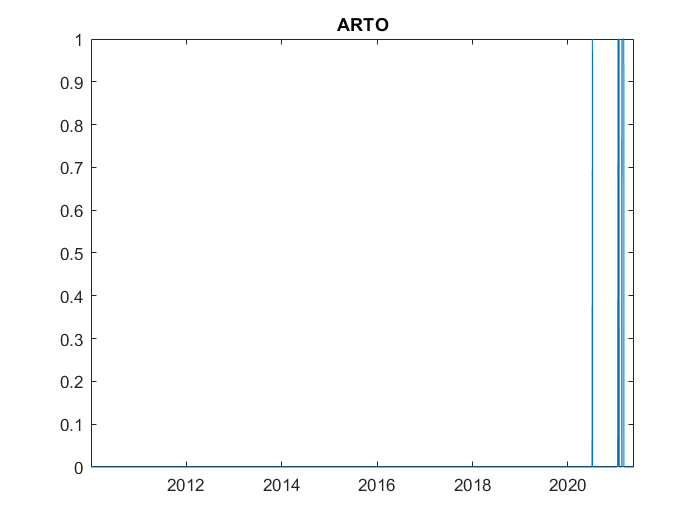


clear A B
A = SymSample;  
B = finalSignal (:, A);
plot (B.Time, B.Variables )
title (A);


clear A B C D


toc

Elapsed time is 0.437792 seconds.


## Transaction cost adjustment

tic

buyFee = 0.2/100;
sellFee = 0.3/100;


% Shift 1 day forward

A = finalSignal.Variables;
TempfinalSignalShift = finalSignal;
B = TempfinalSignalShift.Variables;
B (2:end,:) = A (1:end-1,:) 

B =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

B (1,:) = 0;
TempfinalSignalShift.Variables = B;

tail (finalSignal)

ans = 8×43 timetable
       Time        ABDA    AMRT    ARNA    ARTO    BRNA    CENT    CLEO    CPIN    CSMI    DCII    DEFI    DNET    EKAD    EMTK    ERTX    GEMA    GMTD    INAF    INDS    ITMA    JECC    JTPE    KAEF    KONI    MAPI    MARK    MREI    MTDL    MYOR    PSAB    PTDU    PTSP    SCMA    SKLT    SLIS    STTP    TCPI    TECH

tail (TempfinalSignalShift)

ans = 8×43 timetable
       Time        ABDA    AMRT    ARNA    ARTO    BRNA    CENT    CLEO    CPIN    CSMI    DCII    DEFI    DNET    EKAD    EMTK    ERTX    GEMA    GMTD    INAF    INDS    ITMA    JECC    JTPE    KAEF    KONI    MAPI    MARK    MREI    MTDL    MYOR    PSAB    PTDU    PTSP    SCMA    SKLT    SLIS    STTP    TCPI    TECH

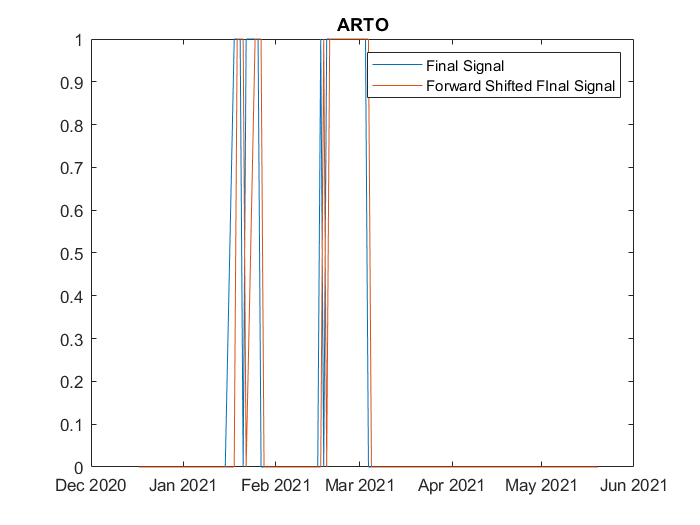



% Check Shifted signal

clear A B
A = SymSample;  
B = finalSignal (end-100:end, A);
C = TempfinalSignalShift (end-100:end, A);
plot (B.Time, B.Variables, C.Time,  C.Variables )
title (A);
legend ("Final Signal", "Forward Shifted FInal Signal")


clear A B C


% Insert transaction cost into signal
% buy cost

buyidx = TempfinalSignalShift.Variables == 0 & finalSignal.Variables == 1 ;
buycost = finalSignal;
buycost.Variables = buyidx .*(1) .* buyFee;

% Check buy cost
tail (finalSignal);
tail (TempfinalSignalShift);
tail (buycost);

% sell cost

sellidx = TempfinalSignalShift.Variables == 1 & finalSignal.Variables == 0 ;
sellcost = finalSignal;
sellcost.Variables = sellidx .* (-1) .* sellFee;

% Check buy cost
tail (finalSignal);
tail (TempfinalSignalShift);
tail (sellcost);

% combined buy and sell cost

transactionCost = finalSignal;
transactionCost.Variables = buycost.Variables + sellcost.Variables;

tail (buycost);
tail (sellcost);
tail (transactionCost);


clear TempfinalSignalShift buycost sellcost buyidx sellidx

toc

Elapsed time is 0.586059 seconds.


## Cumret for trading on each symbol 

tic
% net return for each symbol

dailyret = tick2ret (priceSampleTT);
A = finalSignal(2:end,:);
filteredRet = dailyret ;
filteredRet.Variables = dailyret.Variables .* A.Variables;

netretsym = dailyret;
transactionCostVariables = transactionCost.Variables;
netretsym.Variables = filteredRet.Variables + transactionCostVariables(2:end,:);

% check
tail (finalSignal);
tail (filteredRet);
tail (netretsym);

cumretSym = ret2tick (netretsym);

% rank highest trading cumret 
cumretSymEnd = cumretSym (end, :);
A = transpose (cumretSymEnd.Variables);
B = transpose(string(cumretSymEnd.Properties.VariableNames));
varnametrade = "cumretSymTrade";
C = array2table (A, "VariableNames", varnametrade );
D = array2table (B, "VariableNames","Symbols" );
E = [D C];


cumretSymRank = sortrows (E, varnametrade, "descend")

cumretSymRank = 43×2 table
    Symbols    cumretSymTrade
    _______    ______________

    "INAF"         5.1639    
    "KAEF"         4.6814    
    "TCPI"         2.8072    
    "CPIN"         1.9377    
    "TPIA"         1.4678    
    "PSAB"         1.4003    
    "EKAD"         1.3285    
    "ARTO"         1.2023    
    "MAPI"         1.1833    
    "INDS"         1.1699    
    "ZBRA"         1.1001    
    "SLIS"         1.0973    
    "BRNA"         1.0162    
    "AMRT"         1.0089    
    "TOWR"         1.0073    
    "MYOR"         1.0022    



clear A B C D E cumretSymEnd

A = sortrows (cumretSymRank, "Symbols");
B = sortrows (cumretT, "BuyAndHoldSymbols");
cumretCompare = [A B];
removevars (cumretCompare, "BuyAndHoldSymbols")

ans = 43×3 table
    Symbols    cumretSymTrade    cumretEndValue
    _______    ______________    ______________

    "ABDA"              1            32.539    
    "AMRT"         1.0089            17.788    
    "ARNA"        0.93253            19.329    
    "ARTO"         1.2023             58.96    
    "BRNA"         1.0162            10.662    
    "CENT"        0.97702            10.126    
    "CLEO"              1            11.538    
    "CPIN"         1.9377            14.773    
    "CSMI"              1            11.168    
    "DCII"              1            22.476    
    "DEFI"              1            25.715    
    "DNET"              1            20.723    
    "EKAD"         1.3285            12.903    
    "EMTK"              1            30.959    
    "ERTX"              1            17.882    
    "GEMA"         0.7496                18    


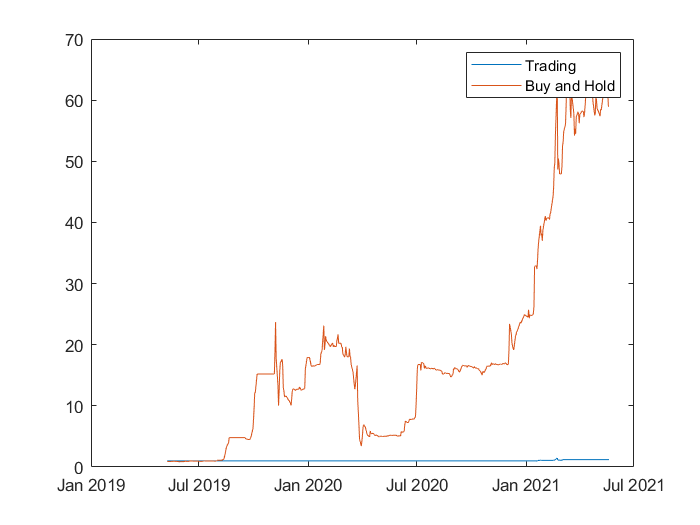


clear A B
% Visualize

A = cumretSym (end-500:end, SymSample);
B = cumret (end-500:end, SymSample);
plot (A.Time, A.Variables, B.Time, B.(SymSample))
legend ("Trading", "Buy and Hold");

clear A B

toc

Elapsed time is 0.288188 seconds.


## Capital Allocation

tic 

dailySignalTT = priceSampleTT (:, 1);
dailySignalTT.Properties.VariableNames = "Daily_Signal";
dailySignalTT.Variables = sum (finalSignal.Variables, 2);

max (dailySignalTT.Variables)

ans = 4


tail (dailySignalTT)

ans = 8×1 timetable
       Time        Daily_Signal
    ___________    ____________

    06-May-2021         0      
    07-May-2021         0      
    10-May-2021         0      
    11-May-2021         0      
    17-May-2021         0      
    18-May-2021         0      
    19-May-2021         0      
    20-May-2021         0      


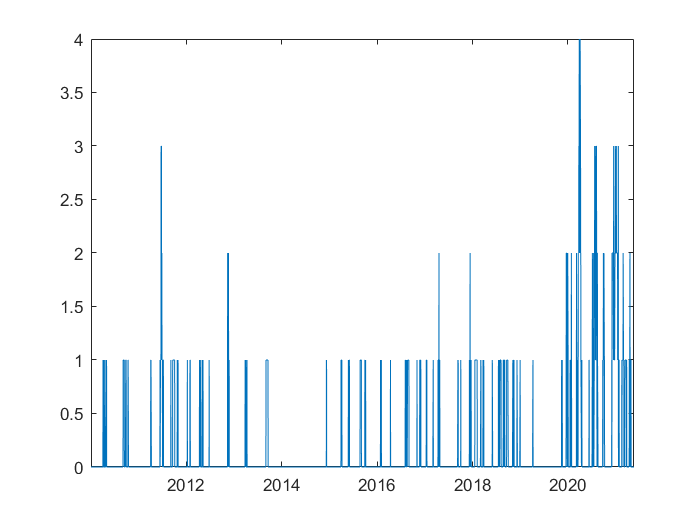


plot (dailySignalTT.Time, dailySignalTT.Variables)


capitalAllocTreshold = 6; % Tag input parameters
capidx = dailySignalTT.Variables > capitalAllocTreshold

capidx = 2825×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0



% preallocation
capAlloc = double (capidx)

capAlloc =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



% Fill the capalloc
% Fill capalloc with # of daily signal > capitalAllocTreshold
nDailySignal = dailySignalTT.Variables;

for i = 1:numel(dailySignalTT.Variables)
    capAlloc(i) = 1/(nDailySignal (i));
    
end

% Fill capalloc with # of daily signal < capitalAllocTreshold
capAlloc (capidx == 0) = 1/ capitalAllocTreshold;

maxCapalloc = max (capAlloc)

maxCapalloc = 0.1667


%capAllocTT = timetable (priceSample.Time, capAlloc, 'VariableNames', "Daily Cap Alloc");

toc

Elapsed time is 0.115123 seconds.


## Capital Allocation Return-Adjusted

tic

% Daily capital allocation per symbol
FinalSignalvar = finalSignal.Variables;
capAllocSym = FinalSignalvar;

for j= 1:size (FinalSignalvar, 2) 
  capAllocSym (:,j) = FinalSignalvar (:,j) .* capAlloc;
    
end

finalret = capAllocSym (2:end,:) .* (netretsym.Variables);

clear capAllocSym FinalSignalvar 

toc

Elapsed time is 0.020490 seconds.


Portfolio daily return summary

tic

% preallocation
dailyPortRet = zeros (size(priceSampleTT.Variables,1),1) ;

dailyPortRet(2:end,:) = sum (finalret, 2);

dailyPortRetTT = timetable (priceSampleTT.Time, dailyPortRet, ...
    'VariableNames',"dailyPortRet");

cumRetPortfolio = ret2tick (dailyPortRetTT);

tail (cumRetPortfolio)

ans = 8×1 timetable
       Time        dailyPortRet
    ___________    ____________

    06-May-2021       3.2819   
    07-May-2021       3.2819   
    10-May-2021       3.2819   
    11-May-2021       3.2819   
    17-May-2021       3.2819   
    18-May-2021       3.2819   
    19-May-2021       3.2819   
    20-May-2021       3.2819   


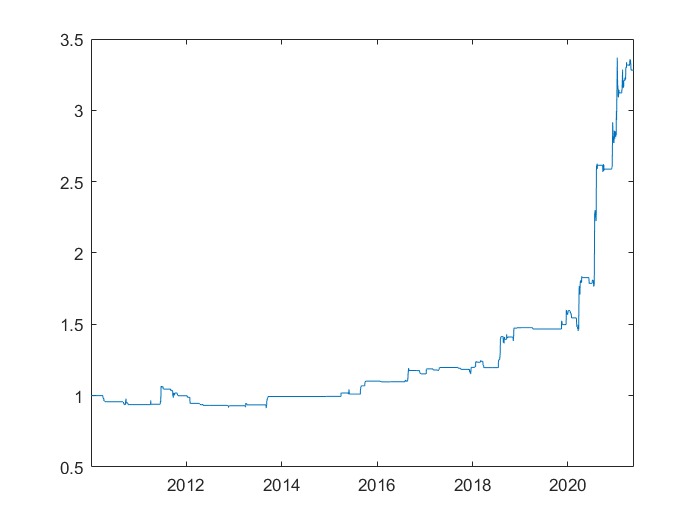


plot (cumRetPortfolio.Time, cumRetPortfolio.Variables)


A= cumRetPortfolio.Variables; 
cumRetPortfolioEndValue = A (end)

cumRetPortfolioEndValue = 3.2819

clear A

time = cumRetPortfolio.Properties.RowTimes;
YearFraction = yearfrac (time(1), time(end))  

YearFraction = 11.3808

CAGR = ((cumRetPortfolioEndValue) ^(1/YearFraction))-1

CAGR = 0.1101


maxDD = maxdrawdown(cumRetPortfolio.Variables)

maxDD = 0.1445


retSD = std (dailyPortRet);
meanRet = mean (dailyPortRet);
SharpeRatio = (meanRet / retSD) * sqrt (252)

SharpeRatio = 1.0376


A = dailyPortRet (dailyPortRet <0);
SortinoRatio = (meanRet / std (A)) * sqrt (252)

SortinoRatio = 0.8955


SharpeR= sharpe (cumRetPortfolio.Variables)

SharpeR = 2.4848


MAR = 0;
Data = dailyPortRet;
% Omega = lpm(-Data, -MAR, 1) / lpm(Data, MAR, 1)
Omega = lpm(-Data, -MAR, 1) / lpm(Data, MAR, 1)

Omega = 1.9221


% Sortino = (mean(Data) - MAR) / sqrt(lpm(Data, MAR, 2))
Sortino = (mean(Data) - MAR) / sqrt(lpm(Data, MAR, 2))

Sortino = 0.1601


% Upside = lpm(-Data, -MAR, 1) / sqrt(lpm(Data, MAR, 2))

Upside = lpm(-Data, -MAR, 1) / sqrt(lpm(Data, MAR, 2))

Upside = 0.3337


clear A dailyPortRet Data capAlloc capidx cumret cumretend 

toc

Elapsed time is 0.151285 seconds.


## Write Output to Excel

writetimetable (cumRetPortfolio, "Trend Trading Input Output Data.xlsx", ...
    'sheet', 'cumRetPortfolio');


## Save workspace data to MatFile

save tradingdata.mat 
